## FRKSKIA001 and CLRCAM007 ES3 

### Prac 2

#### Prac 2.2: Parallel Processing in MATLAB 

2.2.(a) This short task involves implementing the easy Bubble sort routine, just using looping, don’t attempt any parallelization. First implement Bubble sort, in the regular fashion, by using a nested for loop. A good explanation is given at: https://medium.com/codex/bubble-sorthow-it-works-psuedocode-and-c-python-implementationc45306d44827. Apply sorting to a 100x100 matrix of random numbers, you just use rand for generating random floats in the range (0,1). Sort the columns from minimum value to maximum value, like the MATLAB sort command does. i.e. you will need another for loop for go through sorting each column of the matrix one column at a time. (NOTE: obviously not using the built in sort function). [10 marks]

Creating a bubble sort function look at BubbleSort

Testing the Bubble sort function

X=rand(100,100)

X =     0.6235    0.9706    0.0428    0.8001    0.6044    0.6887    0.4216    0.3883    0.0691    0.4253    0.5745    0.5294    0.2620    0.9243    0.6158    0.3861    0.4312    0.2568    0.7430    0.9123    0.2870    0.4133    0.8921    0.3709    0.5055    0.3273    0.8538    0.3610    0.3281    0.1475    0.9633    0.0976    0.4102    0.3569    0.3582    0.2578    0.0805    0.2341    0.7523    0.0605    0.4093    0.3232    0.3235    0.3176    0.7281    0.6036    0.3608    0.8475    0.7159    0.3427
    0.6280    0.2873    0.6198    0.0283    0.1835    0.4474    0.9951    0.1449    0.7553    0.2202    0.2547    0.9659    0.2762    0.0539    0.4662    0.7402    0.7463    0.4924    0.1468    0.0886    0.7305    0.8381    0.8917    0.3733    0.0274    0.7329    0.8218    0.1745    0.4903    0.1716    0.5200    0.1398    0.4434    0.9798    0.8985    0.6838    0.5161    0.5084    0.9730    0.3373    0.6725    0.1324    0.7184    0.9776    0.2554    0.8566    0.9195    0.6046    0.7077    0


for i = 1:100 
  X(:,1) = BubbleSort(X(:,1));
end 

2.2.(b) How does the built-in sort function compare in run time to your sequential sort implementation? Test, at least, for square matrixes of sizes 100, 200, 500, 1000, 10000. [5 marks]

% Initialize the cell array
timetaken = cell(6,4);
timetaken(1,:) = {"size", "bubble sort time", "inbuilt sort time", "speed up"};
timetaken(2:end,1) = num2cell([100; 200; 500; 1000; 1200]); % should use [100; 200; 500; 1000; 10000] but takes too long so using 1100 for know 

% Loop over each row in timetaken
for i = 2:size(timetaken,1)
    % Call the timetest function with the value in the first column of the i-th row
    [timeBubble, timeInbuilt] = timetest(timetaken{i,1});
    timetaken{i,2} = timeBubble;
    timetaken{i,3} = timeInbuilt;
    % Calculate speed up
    timetaken{i,4} = timeBubble/timeInbuilt;
end

    "Time tacken by the bubble sort function was 0.0012235 s. Time tacken by the inbuilt sort function was: 0.0001188 s."

    "Time tacken by the bubble sort function was 0.0088472 s. Time tacken by the inbuilt sort function was: 0.0002996 s."

    "Time tacken by the bubble sort function was 0.1529 s. Time tacken by the inbuilt sort function was: 0.0012341 s."

    "Time tacken by the bubble sort function was 1.063 s. Time tacken by the inbuilt sort function was: 0.0044645 s."

    "Time tacken by the bubble sort function was 1.8336 s. Time tacken by the inbuilt sort function was: 0.0094359 s."




% Display the results
disp(timetaken)

    {["size"]}    {["bubble sort time"]}    {["inbuilt sort time"]}    {["speed up"]}
    {[   100]}    {[            0.0012]}    {[         1.1880e-04]}    {[   10.2988]}
    {[   200]}    {[            0.0088]}    {[         2.9960e-04]}    {[   29.5300]}
    {[   500]}    {[            0.1529]}    {[             0.0012]}    {[  123.8989]}
    {[  1000]}    {[            1.0630]}    {[             0.0045]}    {[  238.0909]}
    {[  1200]}    {[            1.8336]}    {[             0.0094]}    {[  194.3268]}



plotting the grafs

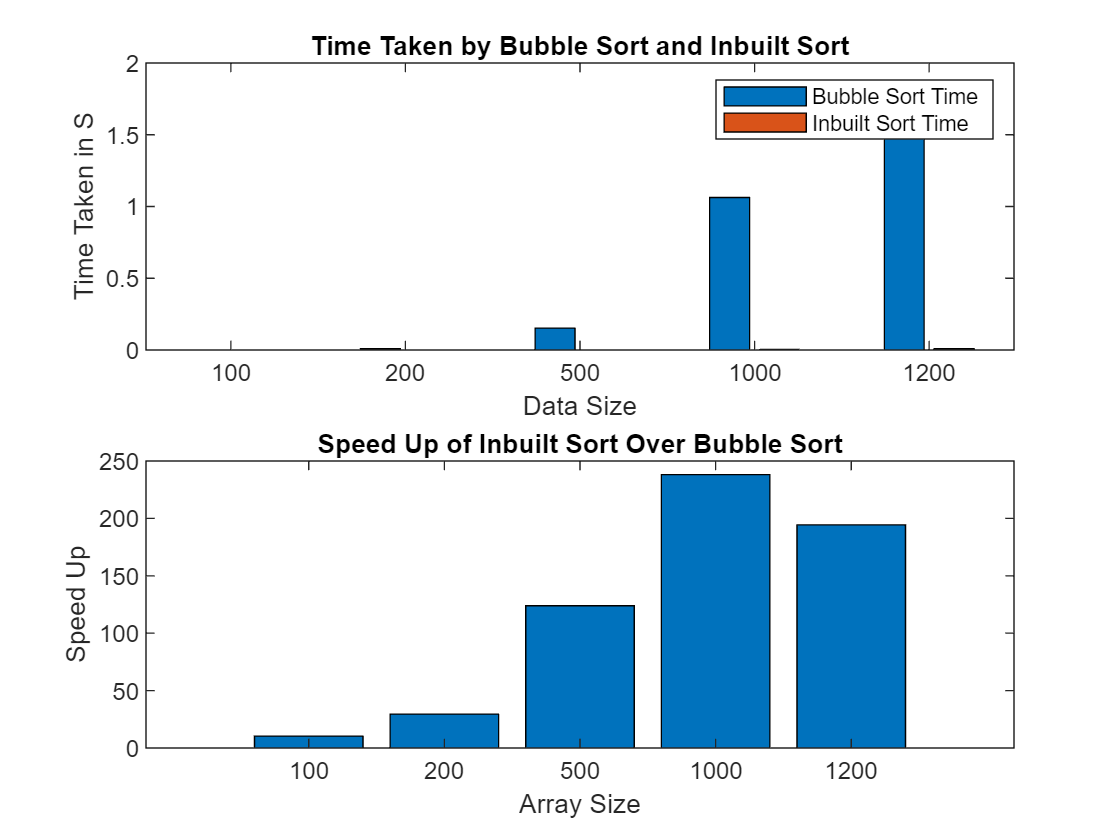

% Create a new figure
figure

% Create the first subplot
subplot(2,1,1)
% Create a bar graph of the time taken by the Bubble Sort function and MATLAB's built-in sort function
bar(cell2mat(timetaken(2:end ,2:3)));
% Add labels and title
xlabel('Data Size')
ylabel('Time Taken in S')
title('Time Taken by Bubble Sort and Inbuilt Sort')

% Change the x-axis labels to an array of your choice
xticklabels(timetaken(2:end,1))

% Add a legend
legend('Bubble Sort Time', 'Inbuilt Sort Time')


% Create the second subplot
subplot(2,1,2)
% Create a bar graph of the speed up
bar(cell2mat(timetaken(2:end ,4)));
% Add labels and title
xlabel('Array Size')
ylabel('Speed Up')
title('Speed Up of Inbuilt Sort Over Bubble Sort')

% Change the x-axis labels to an array of your choice
xticklabels(timetaken(2:end,1))